%midpoint approx
clear
clc
N = [5, 25, 50, 75, 100]

N =      5    25    50    75   100


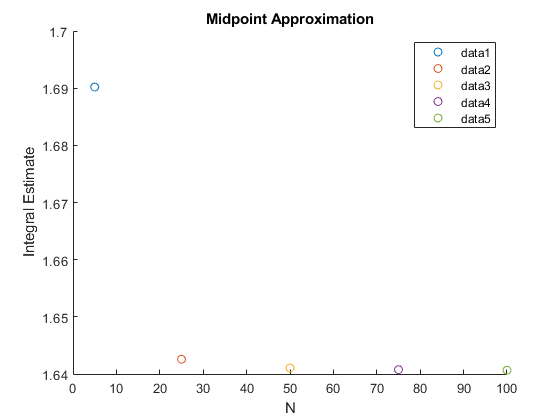

figure
title("Midpoint Approximation")
xlabel("N")
ylabel("Integral Estimate")
hold on
for n = N
    delta_x = 0.8/n;
    x_left = 0 : delta_x : 0.8 - delta_x;
    x_right = 0 + delta_x : delta_x : 0.8;
    x_average = (x_left + x_right)/2;
    series = delta_x*((0.2 + (25.*x_average) - 200.*((x_average).^2) + 675.*((x_average).^3) - 900.*((x_average).^4) + 400.*((x_average).^5)));
    M = sum(series);
    scatter(n, M);
end

legend
hold off




%differential Equation Solving
clear
clc

N = [5, 10, 20, 50]

N =      5    10    20    50


y_0 = 1

y_0 = 1

t_0 = 0

t_0 = 0

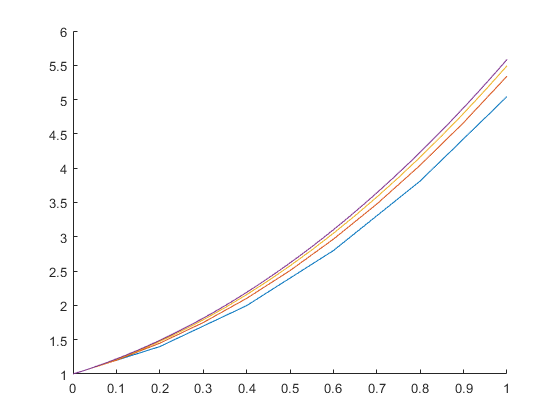

delta_t = 0.2000

sol =      1   NaN   NaN   NaN   NaN   NaN


delta_t = 0.1000

sol =      1   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


delta_t = 0.0500

sol =      1   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


delta_t = 0.0200

sol =      1   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


figure
hold on
for n = N
    delta_t = 1/n
    t = 0:delta_t:1;
    sol = NaN(1, length(t));
    sol(1) = y_0
    for k = 2 : length(t)
        sol(k) = sol(k - 1) + delta_t*((1 + 4*(t(k - 1))) + sqrt(sol(k - 1)));
        %sol(k) = sol(k - 1) + (delta_t/2)*((1 + 4*(t(k - 1) + t(k))) + sqrt(sol(k - 1)) + sol(k));
        
    end
    plot(t, sol)
    
end